clf;
clear;

house = imread("../images/house.tif");
[M,N] = size(house)

M = 512

N = 512

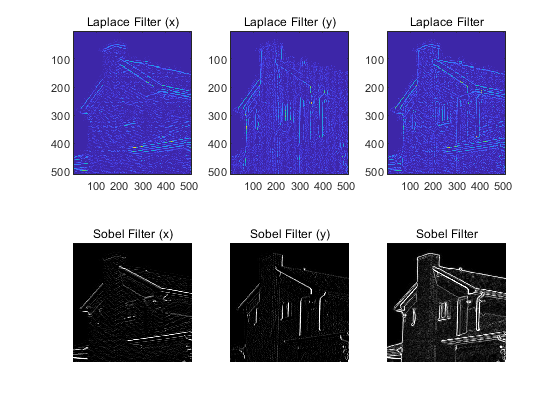

% imshow(house);

Laplace_y = [0 0 0; 1 -2 1; 0 0 0];
Laplace_x = [0 1 0; 0 -2 0; 0 1 0];
Laplace = [0 1 0; 1 -4 1; 0 1 0];
sobel_y = [-1 0 1; -2 0 2; -1 0 1];
sobel_x = [-1 -2 -1; 0 0 0; 1 2 1];

house_double = double(house);
house_sobel = zeros(M,N);
house_sobel_x = zeros(M,N);
house_sobel_y = zeros(M,N);
house_laplace = zeros(M,N);
house_laplace_x = zeros(M,N);
house_laplace_y = zeros(M,N);
for i = 1:M-2
    for j = 1:N-2
        tmp_x = sobel_x.*house_double(i:i+2,j:j+2);
        tmp_y = sobel_y.*house_double(i:i+2,j:j+2);
        tmp_x = sum(tmp_x(:));
        tmp_y = sum(tmp_y(:));
        house_sobel_x(i+1,j+1) = tmp_x;
        house_sobel_y(i+1,j+1) = tmp_y;        
        house_sobel(i+1,j+1) = sqrt(tmp_x^2 + tmp_y^2);

        tmp = Laplace.*house_double(i:i+2,j:j+2);
        tmp = sum(tmp(:));
        tmp_x = Laplace_x.*house_double(i:i+2,j:j+2);
        tmp_x = sum(tmp_x(:));
        tmp_y = Laplace_y.*house_double(i:i+2,j:j+2);
        tmp_y = sum(tmp_y(:));
        house_laplace_x(i+1,j+1) = tmp_x;
        house_laplace_y(i+1,j+1) = tmp_y;
        house_laplace(i+1,j+1) = tmp;
    end
end
house_sobel_x = uint8(house_sobel_x);
house_sobel_y = uint8(house_sobel_y);
house_sobel = uint8(house_sobel);
house_laplace_x = uint8(house_laplace_x);
house_laplace_y = uint8(house_laplace_y);
house_laplace = uint8(house_laplace);

subplot(2,3,1);
imagesc(house_laplace_x);title('Laplace Filter (x)');
subplot(2,3,2);
imagesc(house_laplace_y);title('Laplace Filter (y)');
subplot(2,3,3);
imagesc(house_laplace);title('Laplace Filter');
subplot(2,3,4);
imshow(house_sobel_x);title('Sobel Filter (x)');
subplot(2,3,5);
imshow(house_sobel_y);title('Sobel Filter (y)');
subplot(2,3,6);
imshow(house_sobel);title('Sobel Filter');